download of the dataset and verification of no correlation between the different features through a scatter plot of every feature with the others (could have done a confusion matrix too)

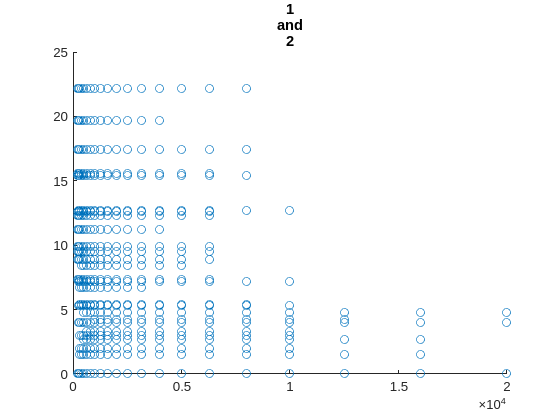

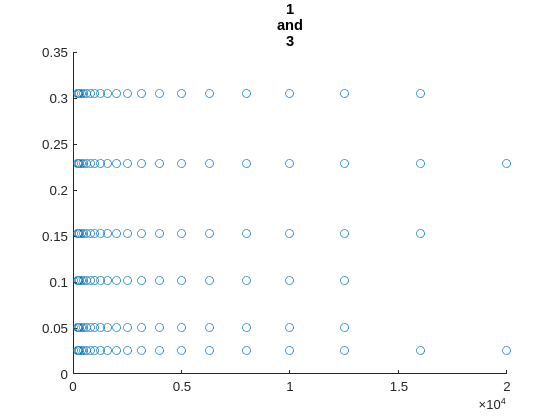

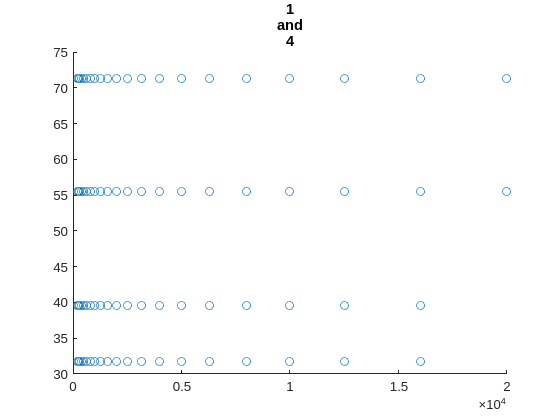

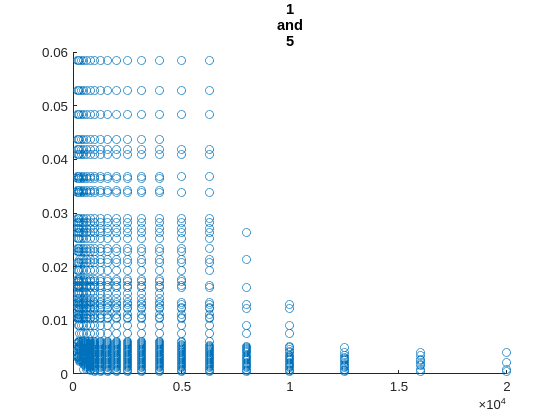

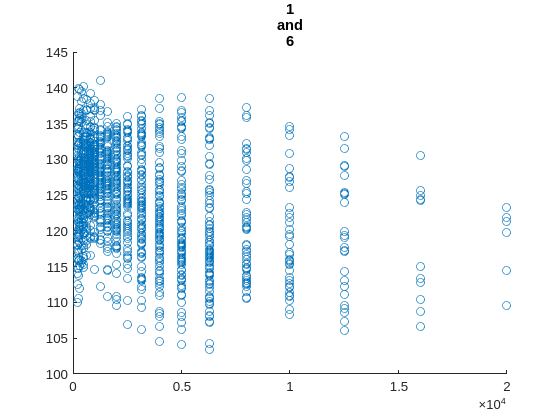

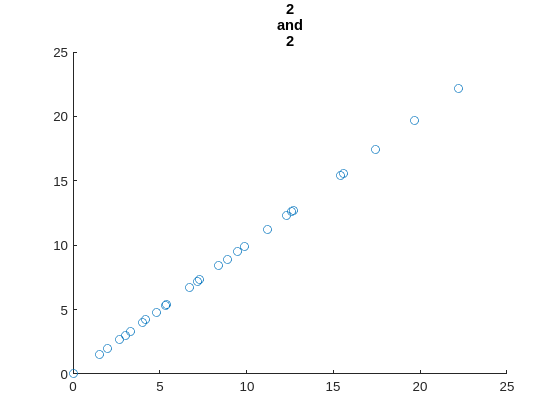

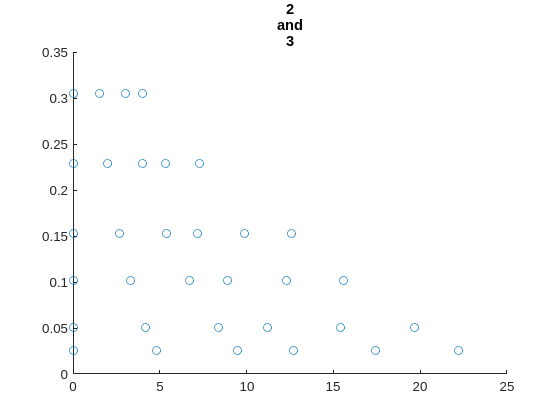

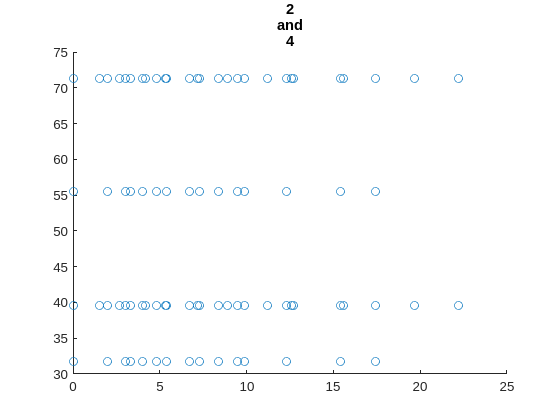

clear, close all;
data=load("airfoil_self_noise.dat");
for i=1:5
    for j=2:6
        figure;
        scatter(data(:,i),data(:,j));
        title([num2str(i) "and" num2str(j)]);
    end
end

let's see for clustering, here the elbow method, we can see the stagnation at 13 clusters

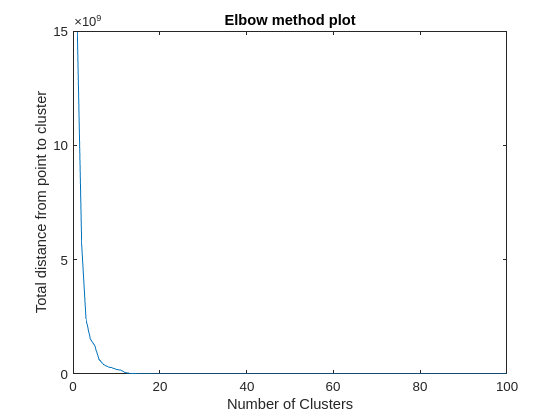

totaldistance=zeros(1,100);
for i=1:100
    [Kid,Kcenters,Kdsum]=kmeans(data,i);
    % Kdsum=Kdsum/max(Kdsum);
    for k=1:length(Kdsum)
        totaldistance(1,i)=totaldistance(1,i)+Kdsum(k);     
    end
end
figure;
plot(totaldistance);
title('Elbow method plot');
xlabel('Number of Clusters');
ylabel('Total distance from point to cluster')

max(data(:,1)) 

ans = 20000

min(data(:,1))

ans = 200

max(data(:,2)) 

ans = 22.2000

min(data(:,2))

ans = 0

max(data(:,3)) 

ans = 0.3048

min(data(:,3))

ans = 0.0254

max(data(:,4)) 

ans = 71.3000

min(data(:,4))

ans = 31.7000

max(data(:,5))

ans = 0.0584

min(data(:,5))

ans = 4.0068e-04

Now let's begin the inference system and problem definition

We have a 5 inputs 1 output FIs that will be trained using a cascading GA and then for the inference, we will use 2 systems, a TSK 1st order and a TSK 0 order to compare efficiency.

train=randperm(1503,ceil(1503*0.8));
points=[];
for p=1:length(data)
    if isempty(find(train==p))
        points=[points p];
    end
end

datatrain=data(train,:);
datatest=data(points,:);


% GA parameters
% stochastic rates :
selection_rate=0.5;
elitism_rate=0.01;
mutation_rate=0.3;

% generational parameters
Popsize=1000;
maxgen=100;

Let's initialize both the TSKs

TSK0_pop=initTSK0(Popsize);
% TSK1_pop=initTSK1(Popsize);
% TSK1_pop=TSK1_pop';
TSK0_pop=TSK0_pop';
parfor i=1:Popsize
    fit0(i)=fitness0(TSK0_pop{i},datatrain,3);
end

now let's do the optimization

bestfit=[];
for gen=1:maxgen
    
    mutation_rate=max(0.5,1-gen/maxgen);
    [num_elites,pool] = selection(TSK0_pop, fit0, selection_rate,Popsize,elitism_rate);
    TSK0_pop = reproduction(pool, mutation_rate, Popsize,num_elites,0);
    
    % now the new fitness
    bestfit(gen)=min(fit0); % store best fitness
    parfor i=1:Popsize
        newfit(i)=fitness0(TSK0_pop{i},datatrain,3);
    end
    fit0=newfit;
    disp(["gen" gen ", best fit = " bestfit(gen)])
end

    "gen"    "1"    ", best fit = "    "13878.6138"

    "gen"    "2"    ", best fit = "    "13677.7837"

    "gen"    "3"    ", best fit = "    "13677.7837"

    "gen"    "4"    ", best fit = "    "13677.7837"

    "gen"    "5"    ", best fit = "    "11142.8162"

    "gen"    "6"    ", best fit = "    "11142.8162"

    "gen"    "7"    ", best fit = "    "11142.8162"

    "gen"    "8"    ", best fit = "    "9249.8747"

    "gen"    "9"    ", best fit = "    "9249.8747"

    "gen"    "10"    ", best fit = "    "9249.8747"

    "gen"    "11"    ", best fit = "    "9249.8747"

    "gen"    "12"    ", best fit = "    "9249.8747"

    "gen"    "13"    ", best fit = "    "9249.8747"

    "gen"    "14"    ", best fit = "    "8460.6439"

    "gen"    "15"    ", best fit = "    "8460.6439"

    "gen"    "16"    ", best fit = "    "8460.6439"

    "gen"    "17"    ", best fit = "    "8460.6439"

    "gen"    "18"    ", best fit = "    "7031.3705"

    "gen"    "19"    ", best fit = "    "7031.37

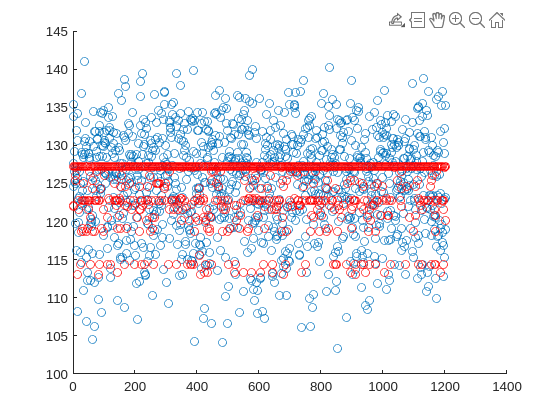

out =   127.2774  122.0837  122.0377  127.2774  127.2774  127.2774  127.2774  125.3494  126.0270  127.2774  127.2774  127.2774  127.2774  127.2774  113.1139  127.2774  127.2774  121.5617  127.2774  122.7355  127.2774  127.2774  127.2774  127.2774  114.3737  127.2774  118.6651  127.2774  127.2774  127.2774  122.7355  119.0360  127.2774  118.6651  125.0374  122.7355  127.2774  127.2774  122.7355  127.2774  122.7355  127.2774  127.2774  127.2774  127.2774  118.6651  122.7355  119.0360  127.2774  122.7355


[~, sorted_idx] = sort(fit0, 'ascend');
out=visu(TSK0_pop{sorted_idx(1)},datatrain,3)

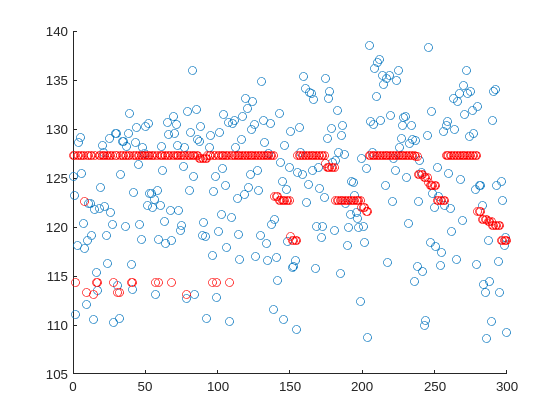

out =   127.2774  127.2774  114.3737  127.2774  127.2774  127.2774  127.2774  127.2774  122.6347  113.3451  127.2774  127.2774  127.2774  127.2774  113.1139  127.2774  114.3737  114.3737  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  114.3737  127.2774  127.2774  113.3451  113.3451  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  114.3737  114.3737  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774  127.2774


[~, sorted_idx] = sort(fit0, 'ascend');
out=visu(TSK0_pop{sorted_idx(1)},datatest,3)

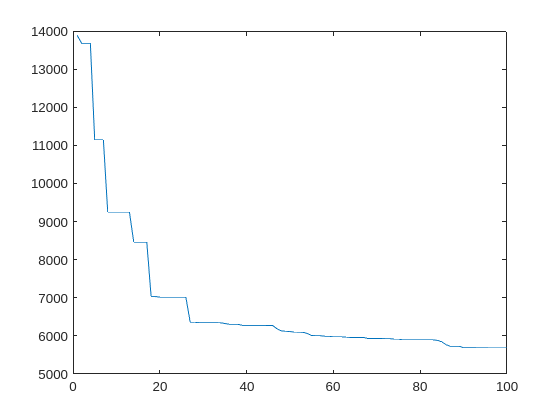

figure;
plot(bestfit)

here are all the functions used in the .mlx

% TSK initializations
%  real mf bounds : 0:20000; 0:25; 0:0.35; 0:75; 0:0.06; 
% syntetic mf : 0:1; 0:1; 0:1 /normalized value
function pop=initTSK0(Popsize)
    pop=cell(Popsize,1);
    bounds=[20000 25 1.1 0.35 1.1 75 1.1 0.06];
    
    rules= zeros(36,3);
    for i=1:Popsize
        mfs=[];
        for k=1:length(bounds)
        base_mf=sort(bounds(k)*rand(1,9));
        base_mf(1)=-1;
        base_mf(9)=bounds(k)+bounds(k)*0.1;
        mfs=[mfs; base_mf([1 2 4]); base_mf([3 5 7]); base_mf([6 8 9])];
        end
        rules(:,1)= 500*rand(36,1);
        pop{i,1}=[mfs;rules];
    end
end
function pop=initTSK1(Popsize)
    pop=cell(Popsize,1);
    for i=1:Popsize
        bounds=[21000 25 1.1 0.35 1.1 75 1.1 0.06];
        mfs=zeros(24,3);
        rules= zeros(36,3);
        for i=1:Popsize
            for k=1:length(bounds)
                base_mf=sort(bounds(k)*rand(1,9));
                base_mf(1)=-2;
                base_mf(9)=bounds(k)+bounds(k)*0.1;
                mfs=[mfs;base_mf([1 2 4]); base_mf([3 5 7]); base_mf([6 8 9])];
            end
            rules= 500*rand(36,3)-50;
            pop{i,1}=[mfs;rules];
        end
    end
end

%selection, mutation, reproduction
function [num_elites,pool] = selection(pop, fitness_vals, rate,popsize,e_rate)
    % popsize = length(pop);
    num_selected = round(rate * popsize);  
    num_elites = ceil(e_rate * popsize);
    [~, sorted_idx] = sort(fitness_vals, 'ascend');
    elites = pop(sorted_idx(1:num_elites));  % Preserve the best individuals

    % Tournament Selection (forces selection pressure)
    num_to_select = num_selected - num_elites;
    selected_individuals = cell(1, num_to_select);
    for i = 1:num_to_select
        % Pick 3 random individuals and select the best one
        candidates = randperm(popsize, 3);
        [~, best_idx] = min(fitness_vals(candidates));
        selected_individuals{i} = pop{candidates(best_idx)};
    end

    % Combine elites and selected individuals
    pool = [elites, selected_individuals];
end

function child = mutation(child, mutation_rate,flag)
    if rand < mutation_rate
        if flag==0
            %apply a random multiplier to every component 
            for i=1:3
                for n=1:60
                    if n<=24
                        if ~((i==1 && mod(n+2,3)==0) || (i==3 && mod(n,3)==0))
                        multiplier=1 + 0.6 * (rand(1) - 0.5);
                        child(n,i)=child(n,i)*multiplier;
                        end
                    else
                        multiplier=1 + 0.6 * (rand(1) - 0.5);
                        child(n,i)=child(n,i)*multiplier;
                    end
                end
            end
        else
            %apply a random multiplier to every component 
            for i=1:5
                for n=1:60
                    if n<=24
                        if ~((i==1 && mod(n+2,3)==0) || (i==3 && mod(n,3)==0))
                        multiplier=1 + 0.6 * (rand(1) - 0.5);
                        child(n,i)=child(n,i)*multiplier;
                        end
                    else
                        multiplier=1 + 0.6 * (rand(1) - 0.5);
                        child(n,i)=child(n,i)*multiplier;
                    end
                end
            end
        end
        
    end
end

function new_pop = reproduction(pool, mutation_rate, popsize,num_elites,flag)
    new_pop = cell(1, popsize);
    
    for i = 1:num_elites
        new_pop{i} = pool{i}; % Directly copy elite individuals
    end
    for i = num_elites+1:popsize
        parent1 = pool{randi(length(pool))}; %select parents
        parent2 = pool{randi(length(pool))};
        
        % we want to do crossover on each membership function by doing an
        % average of the parents parameters % to fix
        if flag==1 % for tsk1
            child=zeros(60,5);
            for k=1:8 % for each input
                alpha=rand(1); beta=1-alpha;
                memberlist=[parent1(3*k-2,:) parent1(3*k-1,:) parent1(3*k,:); parent2(3*k-2,:) parent2(3*k-2,:) parent2(3*k-2,:)];
                newmf=alpha*memberlist(1,:)+beta*memberlist(2,:);
                newmf=sort(newmf);
                child(3*k-2,:)=newmf([1 2 4]); 
                child(3*k-1,:)=newmf([3 5 7]) ;
                child(3*k,:)=newmf([6 8 9]);
                % child(k,:)=(alpha*parent1(k,:)+beta*parent2(k,:));
            end
            for k=25:60
                if k>=48
                    child(k,:)=parent1(k,:);
                else
                    child(k,:)=parent2(k,:);
                end
            end
        else %for tsk0
            child=zeros(60,3);
            for k=1:8 % for each input
                alpha=rand(1); beta=1-alpha;
                memberlist=[parent1(3*k-2,:) parent1(3*k-1,:) parent1(3*k,:); parent2(3*k-2,:) parent2(3*k-1,:) parent2(3*k,:)];
                newmf=alpha*memberlist(1,:)+beta*memberlist(2,:);
                newmf=sort(newmf);
                child(3*k-2,:)=newmf([1 2 4]); 
                child(3*k-1,:)=newmf([3 5 7]) ;
                child(3*k,:)=newmf([6 8 9]);
            end
            for k=25:60
                if k>=48
                    child(k,:)=parent1(k,:);
                else
                    child(k,:)=parent2(k,:);
                end
            end
        end
        
        % Mutation
        child = mutation(child, mutation_rate,flag);
        
        new_pop{i} = child;
    end
end

% membership function
function mu = triangle(x,le,ce,re)    %TRIANGLE MEMBERSHIP FUNCTION
    if x >= le & x < ce
       mu = (x - le)/(ce - le);
    elseif x >= ce & x <= re
       mu = (re - x)/(re - ce);
    else
     mu = 0;
    end
    %mu=num2str(mu);
end

% fitness function
function f=fitness0(chr, data,membernum)
%chr first 24 lines are membership values and the rest are the rules (36
%rules)
    d=[1 2 3 4 5];
    for i=1:4
        if i~=1
            norm_out=output/max(abs(output));
        end
        for ind=1:length(data) % a la place, faire passer tous les points dans chaque FIS puis normaliser la liste de résultats
             % number of FIS
             %kejhbv=pltmf(data(:,1),chr)
            if i==1 % first iteration use 2 real inputs % goes for input 1 and 2
                for k=1:membernum % goes through each of the 3 membership functions
                    mu(1,k)=triangle(data(ind,d(i)),chr(k,1),chr(k,2),chr(k,3));
                    mu(2,k)=triangle(data(ind,d(i+1)),chr(k+3,1),chr(k+3,2),chr(k+3,3));

                end
                
            else 
                
                for k=1:membernum % gives the membership based on the intermediate output
                    mu(1,k)=triangle(norm_out(ind),chr(k+6*(i-1),1),chr(k+6*(i-1),2),chr(k+6*(i-1),3));
                end
                
                for k=1:membernum % gives the membership based on the intermediate output
                    mu(2,k)=triangle(data(ind,d(i+1)),chr(k+6*(i-1)+3,1),chr(k+6*(i-1)+3,2),chr(k+6*(i-1)+3,3));
                end
            end
            % end of the membership computing, start of rules activation computing
            rindex=0; % index of the rule (1 to 9 )
            for k=1:membernum % goes through each membership of input 1
                for n=1:membernum % goes through each membership of input 2
                    rindex=rindex+1; % go to next rule (should go up to 9)
                    rmu(rindex)=min(mu(1,k),mu(2,n)); % get the activation of the rule based on every combinaisons       
                end
            end
            agregg=sum(rmu); % get the aggregation of the activation
            
            % begin the defuzzification
            
            for p=1:rindex % go through every rule
                output_raw(ind,p)=rmu(p)*chr(9*(i-1)+p+24,1); % i*9-9+p to get to the rule in question and +24 to bypass the 24 membership lines, only first component because TSK 0 order 
            end
            % normalization of the output if intermediary
            if agregg==0
                hgv=1; %% problem in the mf for input 4
            end
            output(ind)=sum(output_raw(ind,:))/agregg; % get the centroid defuzzification
            % if i~=4
            %     norm_out=tanh(output);
            % end
        end
        % let's get the fitness by using the MSRE
        
        
    end
    error=abs(output'-data(:,6));
    f=sum(error); % normalize the fitness
end

function out=visu(chr, data,membernum)
%chr first 24 lines are membership values and the rest are the rules (36
%rules)
    d=[1 2 3 4 5];
    for i=1:4
        if i~=1
            norm_out=output/max(abs(output));
        end
        for ind=1:length(data) % a la place, faire passer tous les points dans chaque FIS puis normaliser la liste de résultats
             % number of FIS
             %kejhbv=pltmf(data(:,1),chr)
            if i==1 % first iteration use 2 real inputs % goes for input 1 and 2
                for k=1:membernum % goes through each of the 3 membership functions
                    mu(1,k)=triangle(data(ind,d(i)),chr(k,1),chr(k,2),chr(k,3));
                    mu(2,k)=triangle(data(ind,d(i+1)),chr(k+3,1),chr(k+3,2),chr(k+3,3));

                end
                
            else 
                
                for k=1:membernum % gives the membership based on the intermediate output
                    mu(1,k)=triangle(norm_out(ind),chr(k+6*(i-1),1),chr(k+6*(i-1),2),chr(k+6*(i-1),3));
                end
                
                for k=1:membernum % gives the membership based on the intermediate output
                    mu(2,k)=triangle(data(ind,d(i+1)),chr(k+6*(i-1)+3,1),chr(k+6*(i-1)+3,2),chr(k+6*(i-1)+3,3));
                end
            end
            % end of the membership computing, start of rules activation computing
            rindex=0; % index of the rule (1 to 9 )
            for k=1:membernum % goes through each membership of input 1
                for n=1:membernum % goes through each membership of input 2
                    rindex=rindex+1; % go to next rule (should go up to 9)
                    rmu(rindex)=min(mu(1,k),mu(2,n)); % get the activation of the rule based on every combinaisons       
                end
            end
            agregg=sum(rmu); % get the aggregation of the activation
            
            % begin the defuzzification
            
            for p=1:rindex % go through every rule
                output_raw(ind,p)=rmu(p)*chr(9*(i-1)+p+24,1); % i*9-9+p to get to the rule in question and +24 to bypass the 24 membership lines, only first component because TSK 0 order 
            end
            % normalization of the output if intermediary
            if agregg==0
                hgv=1; %% problem in the mf for input 4
            end
            output(ind)=sum(output_raw(ind,:))/agregg; % get the centroid defuzzification
            % if i~=4
            %     norm_out=tanh(output);
            % end
        end
        % let's get the fitness by using the MSRE
        
        
    end
    error=abs(output'-data(:,6));
    f=sum(error); % normalize the fitness
    
    figure;
    scatter(linspace(0,length(data(:,6)),length(data(:,6))),data(:,6))
    hold on 
    scatter(linspace(0,length(data(:,6)),length(data(:,6))),output,"red")

    out=output;
end
